**Simulazione Risposta ad una funzione a gradino**

Si vuole capire l'andamento dei dati misurati:

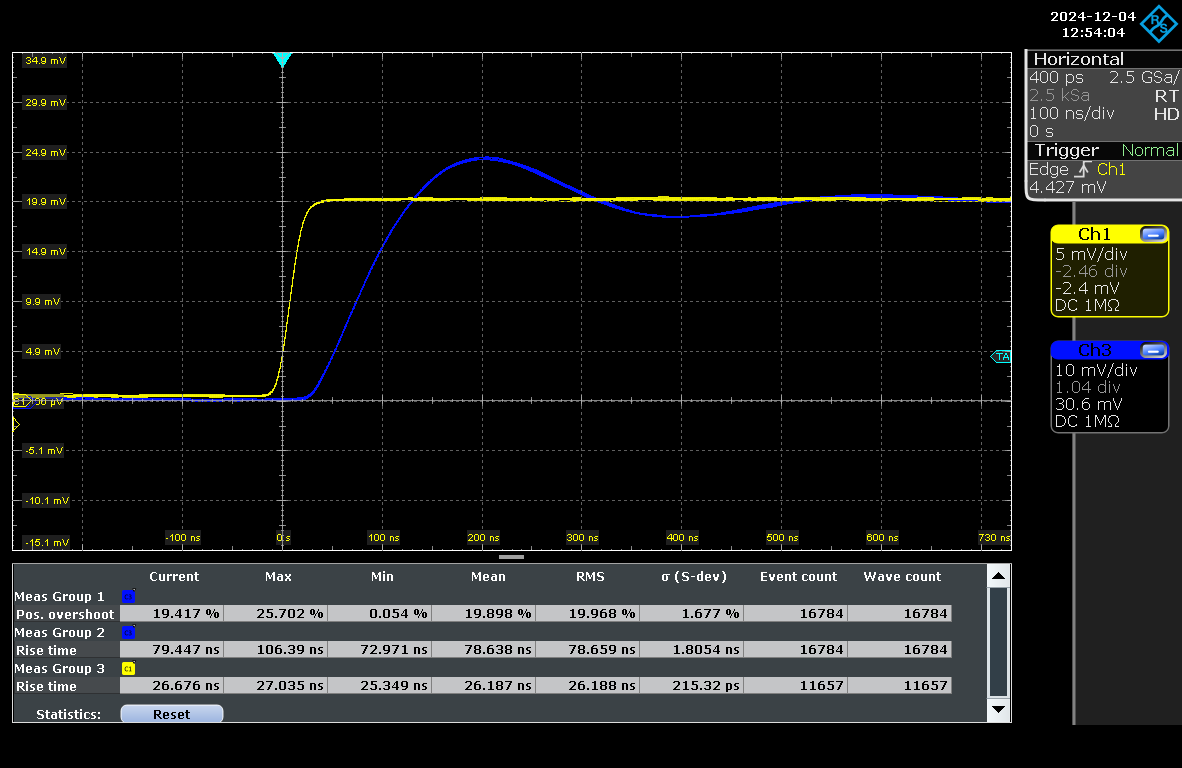

L'operazionale in questione è il OP27 che risulta essere un amplificatore a singolo polo dominante.

In questo file vogliamo comprendere l'andamento di overshoot.

**Singolo Polo Dominante**

Se consideriamo l'amplificatore non ideale con un singolo polo dominante:


$$A\left(s\right)=\frac{A_0 }{1+s\;\tau_A }$$


La risposta del circuito con singolo polo dominante risulta proporzionale alla seguente:

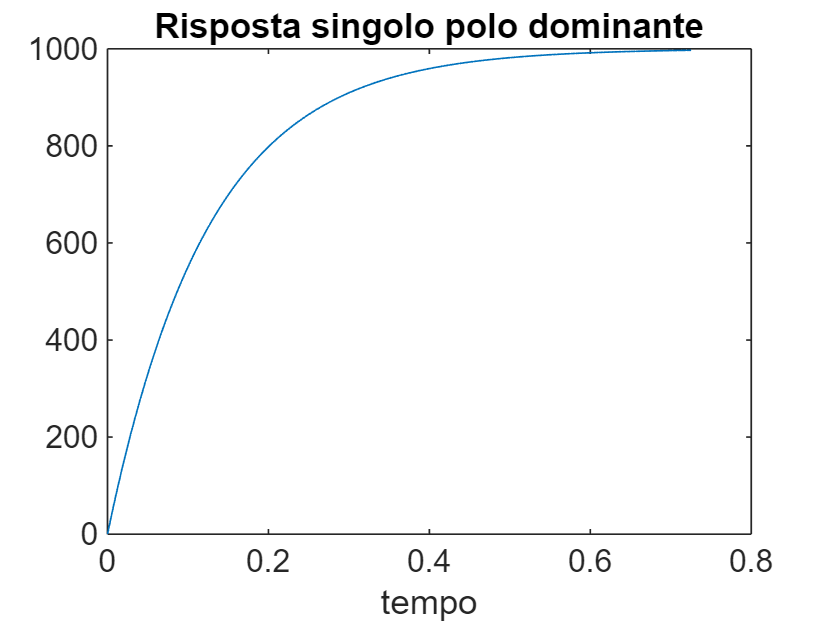

A_o = 1e3;
tau_a = 1/8;    %Posizione polo dominante nell'OP27 preso dai datasheet
sys = tf(A_o, [tau_a, 1]);

[y, tOut] = step(sys);
f = figure(1);
plot(tOut, y)
title('Risposta singolo polo dominante')
xlabel('tempo')

E' evidente che in un circuito a singolo polo non è possibile ottenere overshoot.

**Capacità Parassite**

Per comprendere le misurazioni è utile considerare la presenza di capacità parassite parallele alle resistenze.

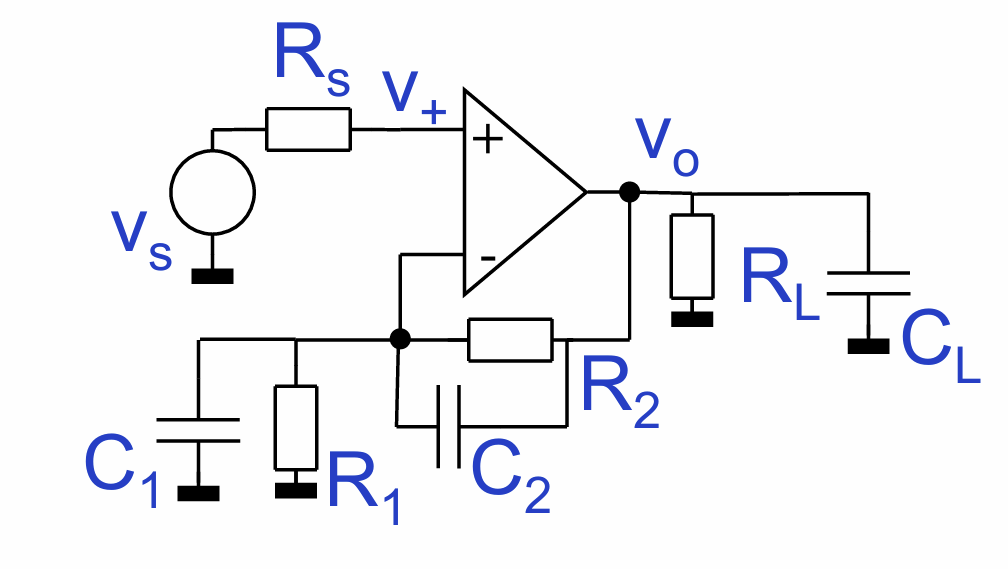

Si ottiene infatti una funzione di trasferimento della tipologia (presa dal pdf delle lezioni al [link](https://pessina.mib.infn.it/Corsi_del_III_anno/CorsoStrumentazioneElettronica/Corso_2425/Amplificatori_reazionati_analisi_tempo_frequenza_B_2425.pdf)):


$$T\left(s\right)=\frac{1}{\beta }A\left(s\right)$$



$$T\left(s\right)=\frac{R_1 }{R_1 +R_2 }\frac{1+{\textrm{sC}}_2 R_2 }{1+s\left(C_1 +C_2 \right)\left(\frac{R_1 R_2 }{R_1 +R_2 }\right)}\;A\left(s\right)$$


inserendo $A\left(s\right)=\frac{A_o }{1+s\tau_A }$ e impostando $\tau_{1=\;} \left(C_1 +C_2 \right)\left(\frac{R_1 R_2 }{R_1 +R_2 }\right)$ e $\tau_2 =R_2 C_2$

si ottiene:


$$T\left(s\right)=\frac{R_1 }{R_1 +R_2 }\frac{1+s\tau_2 }{\left(1+s\tau_1 \right)}\frac{A_o }{\left(1+s\tau_A \right)}$$



$$T\left(s\right)=\frac{R_1 }{R_1 +R_2 }\frac{\left(1+s\tau_2 \right)\;A_o }{\left\lbrack \tau_{A\;} \tau_1 {\;s}^2 +\left(\tau_A {\;+\;\tau }_1 \right)\;s+1\right\rbrack }\;$$


da cui si deduce un andamento a polo doppio.

E' possibile vedere ciò nella simulazione seguente:

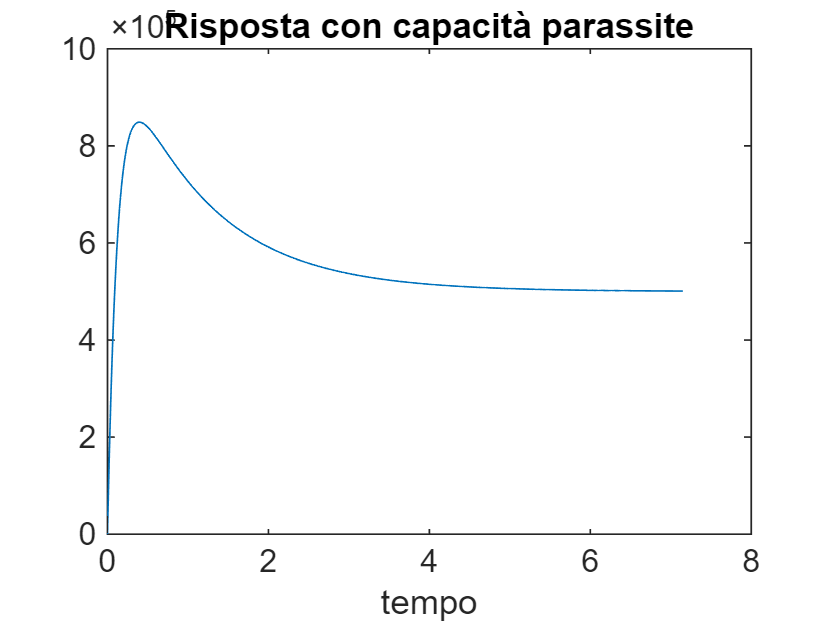

R1 =2200;
R2 = 2200;
C1 = 1e-12;                   %Capacità parassite
C2 = 1e-3;

t1 = (C1+C2)*(R1*R2)/(R1+R2); % corrisponde a tau_1
t2 = C2*R2;                   % corrisponde a tau_2
ta = 1/8;                     % suppongo il polo sia a 8Mhz
beta = R1/(R2+R1);            % 1/beta
A_o = 1e6;

num = [t2, 1];               % numeratore
den = [(t1*ta), (t1+ta), 1]; % denominatore

sys = A_o * beta * tf(num, den);

[y, tOut] = step(sys);

figure(2);
plot(tOut, y);
title('Risposta con capacità parassite');
xlabel('tempo');

Dalla simulazione è evidente che sono necessarie capacità troppo grandi per poter avere un effetto significativo con resistenze nell'odine dei kilo ohm.

L'unica altra possibilità è considerando l'amplificatore con più di un polo.


$$A\left(s\right)=\frac{A_O }{\left(1+s\;\tau_1 \right)\left(1+s\;\tau_2 \right)}$$


E quindi una funzione di trasferimento del genere:


$$T\left(s\right)=\frac{A\left(s\right)}{\beta }=\frac{R_1 }{R_1 +R_2 }\frac{A_o }{\left(1+s\;\tau_1 \right)\left(1+s\;\tau_2 \right)}$$


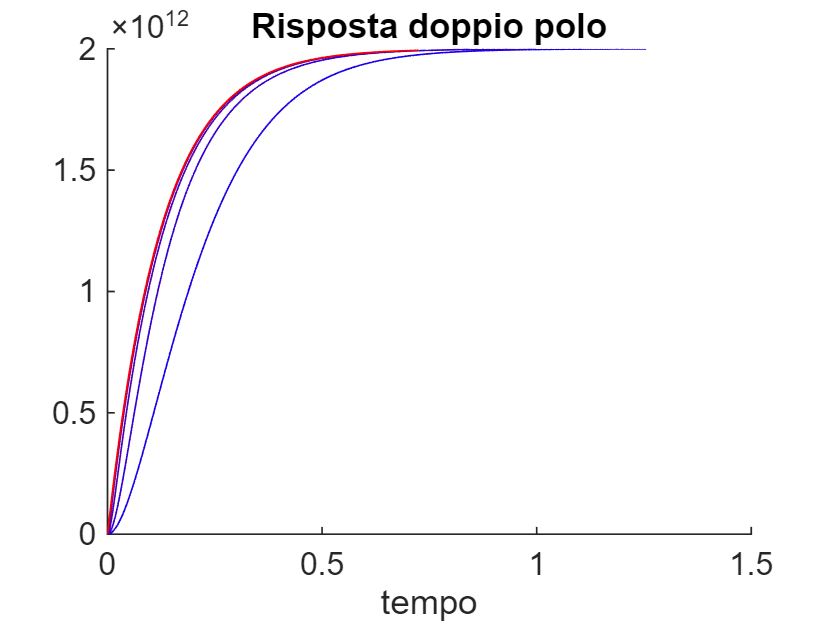

R1 = 2.2e3;
R2 = 2.2e3;
figure(3);
hold on;

r = logspace(1, 6, 10);

for i = 1:length(r)
    
    tau_1 = 1/8;
    tau_2 = 1/r(i);
    
    beta = (R1+R2)/R1;            % 1/beta
    A_o = 1e6;
    
    a = (tau_1 * tau_2);
    b = (tau_1 + tau_2);

    den = [a, b, 1]; % denominatore
    % den = [1, 1, 1];
    
    sys = beta * A_o * tf(A_o, den);
    
    [y, tOut] = step(sys);
    info = stepinfo(sys);
    
    plot(tOut, y, Color=[i/length(r), 0, 1-i/length(r)]);
    title('Risposta doppio polo');
    xlabel('tempo');
end